# Sensitivity of a flux balance analysis solution with respect to input data

## Author(s): Ronan M.T. Fleming, Leiden University

## Reviewer(s): 

## INTRODUCTION

Consider an FBA problem


$$
\begin{array}{ll}
\textrm{max} & c^{T}v\\
\text{s.t.} & Sv=b\\
 & l\leq v\leq u
\end{array}
\end{equation}$$


The local sensitivity of the optimal objective value $\mathcal{L}^{\star} = c^{T}v^{\star}$  with respect to a changes in the input data $\left\lbrace b,l,u\right\rbrace$ is given by

 
$$\frac{\partial\mathcal{L}^{\star}}{\partial b} = y^{\star} \\
\frac{\partial\mathcal{\mathcal{L}^{\star}}}{\partial l} = -w_{l}^{\star} \\
\frac{\partial\mathcal{\mathcal{L}^{\star}}}{\partial u} = w_{u}^{\star}
$$


where $y^{\star}$ is a vector of shadow prices and $w = w_{l}-w_{u}$ is a vector of reduced costs. That is, a shadow price is the partial derivative of the optimal value of the objective function with respect to $b_i$.  It indicates how much net production, or net consumption, of each metabolite increases (positive), or decreases (negative), the optimal value of the objective. The reduced costs, $-w_l$ and $w_{u\;}$are the partial derivative of the optimal value of the objective function with respect to the lower and upper bounds on a reaction, respectively. They indicate how much relaxation, or tightening, of each bound increases, or decreases, the optimal objective, respectively. In the COBRA Toolbox, shadow prices and reduced costs are calculated by `optimizeCbModel`. When using the function

`FBAsolution = optimizeCbModel(model,'max');`

the shadow prices and reduced costs are given by `FBAsolution.y `and` FBAsolution.w`, respectively. 

For a more complete theoretical description, see: cobratoolbox/tutorials/intro_sensitivityAnalysis.pdf

## MATERIALS - EQUIPMENT SETUP

Please ensure that all the required dependencies (e.g. , `git` and `curl`) of The COBRA Toolbox have been properly installed by following the installation guide [here](https://opencobra.github.io/cobratoolbox/stable/installation.html). Please ensure that the COBRA Toolbox has been initialised (tutorial_initialize.mlx) and verify that the pre-packaged LP and QP solvers are functional (tutorial_verify.mlx).

## PROCEDURE

## Load E. coli core model

The most direct way to load a model into The COBRA Toolbox is to use the `readCbModel` function. For example, to load a model from a MAT-file, you can simply use the filename (with or without file extension). 

fileName = 'ecoli_core_model.mat';
if ~exist('modelOri','var')
modelOri = readCbModel(fileName);
end
%backward compatibility with primer requires relaxation of upper bound on
%ATPM
modelOri = changeRxnBounds(modelOri,'ATPM',1000,'u');
model = modelOri;
%setp the matlab e.coli metabolic map parameters
outputFormatOK = changeCbMapOutput('matlab');
map=readCbMap('ecoli_core_map');
options.zeroFluxWidth = 0.1;
options.rxnDirMultiplier = 10;

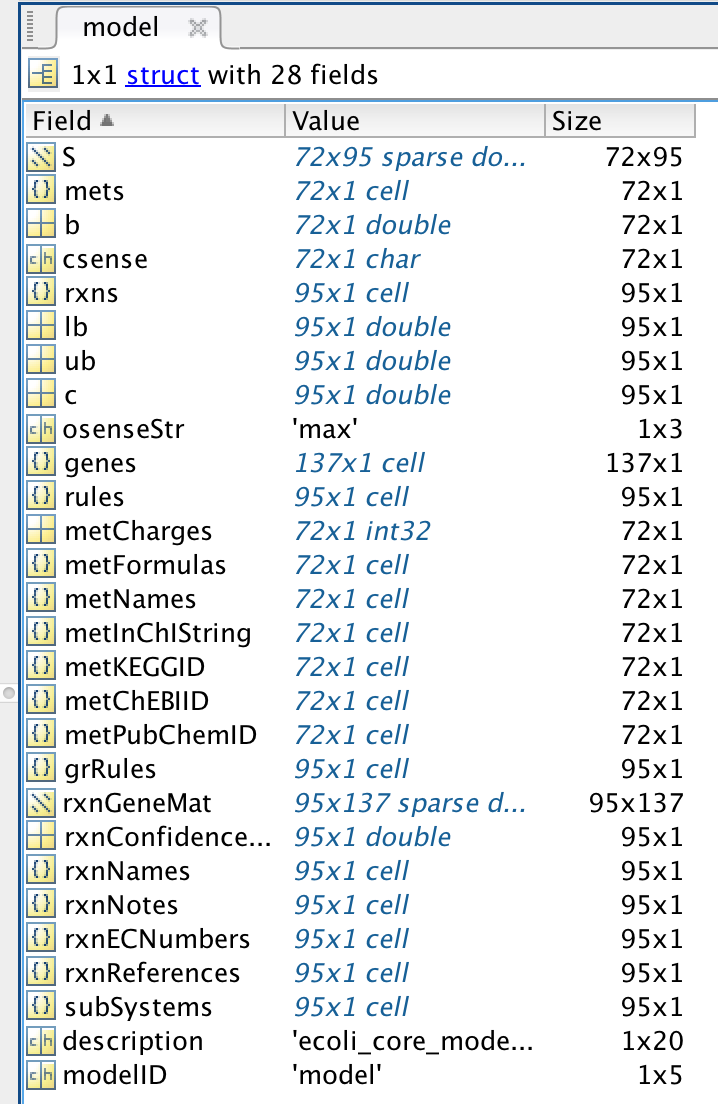

The meaning of each field in a standard model is defined in the [standard COBRA model field definition](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/notes/COBRAModelFields.md).

In general, the following fields should always be present: 

- **S**, the stoichiometric matrix

- **mets**, the identifiers of the metabolites

- **b**, Accumulation (positive) or depletion (negative) of the corresponding metabolites. 0 Indicates no concentration change.

- **csense**, indicator whether the b vector is a lower bound ('G'), upper bound ('L'), or hard constraint 'E' for the metabolites.

- **rxns**, the identifiers of the reactions

- **lb**, the lower bounds of the reactions

- **ub**, the upper bounds of the reactions

- **c**, the linear objective

- **genes**, the list of genes in your model 

- **rules**, the Gene-protein-reaction rules in a computer readable format present in your model.

- **osenseStr**, the objective sense either `'max'` for maximisation or `'min'` for minimisation

## Sensitivity Analysis

#### In the E. coli core model, when maximising ATP production, what is the shadow price of cytosolic protons? 

#### Hint: `FBAsolution.y`

#### What is your biochemical interpretation of this change in objective in the current context?

#### Hint: printFluxVector, drawFlux

#### Perturb the model in such a way as to increase the optimal rate of ATP hydrolysis ('ATPM') by exactly one unit. How does this compare with the theoretical prediction?

#### Hint: change model.b

#### In the E. coli core model, when maximising ATP production, what is the reduced cost of glucose exchange? 

#### Hint: FBAsolution.rcost

#### What is your biochemical interpretation of this?

#### Hint: use drawFlux with a perturbed optimal reaction rate vector

#### Perturb the model in such a way as to increase the optimal rate of ATP hydrolysis ('ATPM') by exactly 17.5 units. How does this compare with the theoretical prediction?

#### Hint: change model.lb

## TROUBLESHOOTING

Note that, if an optimization problem is reformulated from a maximisation to a minimisation problem, then the signs of each of the dual variables is reversed.

## TIMING

*1 hr.*

## ANTICIPATED RESULTS

Understanding of how an optimal objective will change in response to changing the input data.

## *Acknowledgments*

Part of this tutorial was originally written by Jeff Orth and Ines Thiele for the publication "What is flux balance analysis?"

## REFERENCES

1.    Orth. J., Thiele, I., Palsson, B.O., What is flux balance analysis? Nat Biotechnol. Mar; 28(3): 245–248 (2010).

2. Laurent Heirendt & Sylvain Arreckx, Thomas Pfau, Sebastian N. Mendoza, Anne Richelle, Almut Heinken, Hulda S. Haraldsdottir, Jacek Wachowiak, Sarah M. Keating, Vanja Vlasov, Stefania Magnusdottir, Chiam Yu Ng, German Preciat, Alise Zagare, Siu H.J. Chan, Maike K. Aurich, Catherine M. Clancy, Jennifer Modamio, John T. Sauls, Alberto Noronha, Aarash Bordbar, Benjamin Cousins, Diana C. El Assal, Luis V. Valcarcel, Inigo Apaolaza, Susan Ghaderi, Masoud Ahookhosh, Marouen Ben Guebila, Andrejs Kostromins, Nicolas Sompairac, Hoai M. Le, Ding Ma, Yuekai Sun, Lin Wang, James T. Yurkovich, Miguel A.P. Oliveira, Phan T. Vuong, Lemmer P. El Assal, Inna Kuperstein, Andrei Zinovyev, H. Scott Hinton, William A. Bryant, Francisco J. Aragon Artacho, Francisco J. Planes, Egils Stalidzans, Alejandro Maass, Santosh Vempala, Michael Hucka, Michael A. Saunders, Costas D. Maranas, Nathan E. Lewis, Thomas Sauter, Bernhard Ø. Palsson, Ines Thiele, Ronan M.T. Fleming, **Creation and analysis of biochemical constraint-based models: the COBRA Toolbox v3.0**, Nature Protocols, volume 14, pages 639–702, 2019 [doi.org/10.1038/s41596-018-0098-2](https://doi.org/10.1038/s41596-018-0098-2).